clear all;
file = 'A09T.mat';


cd('C:\Users\User\Downloads\Compressed\BCICIV_2a_gdf\') 
load(file);     %load data
cd('C:\Users\User\Downloads\Compressed\BCICIV_2a_gdf\true_labels') 
load(file);      %load true label of subject 
pos_nan = find(isnan(s));
s(pos_nan) = 0;
cd('C:\Users\User\Downloads\Compressed\BCICIV_2a_gdf\') 
eeg = struct();
eeg.fs = h.SampleRate;

%find the position of each class
LH_po = h.TRIG(find(classlabel == 1)); 
RH_po = h.TRIG(find(classlabel == 2));
FE_po = h.TRIG(find(classlabel == 3));
TO_po = h.TRIG(find(classlabel == 4));

%Left hand
for i=1:length(LH_po)
    eeg.data.lh(i,:,:) = [s((LH_po(i)+0*eeg.fs:LH_po(i)+6.999*eeg.fs), [8,10,12])];
end
for i=1:72
    x_value = eeg.data.lh(i,:,:);
    eeg.fil_data.lh(i,:,:) = bp_filter(5, 8, 30, eeg.fs, x_value);
end

% Right hand
for i=1:length(RH_po)
    eeg.data.rh(i,:,:) = [s((RH_po(i)+0*eeg.fs:RH_po(i)+6.999*eeg.fs), [8,10,12])];
end
for i=1:72
    x_value = eeg.data.rh(i,:,:);
    eeg.fil_data.rh(i,:,:) = bp_filter(5, 8, 30, eeg.fs, x_value);
end

%foot
for i=1:length(FE_po)
    eeg.data.fe(i,:,:) = [s((FE_po(i)+00*eeg.fs:FE_po(i)+6.999*eeg.fs), [8,10,12])];
end
for i=1:72
    x_value = eeg.data.fe(i,:,:);
    eeg.fil_data.fe(i,:,:) = bp_filter(5, 8, 30, eeg.fs, x_value);
end

%Tongue
for i=1:length(TO_po)
    eeg.data.to(i,:,:) = [s((TO_po(i)+0*eeg.fs:TO_po(i)+6.999*eeg.fs), [8,10,12])];
end
for i=1:72
    x_value = eeg.data.to(i,:,:);
    eeg.fil_data.to(i,:,:) = bp_filter(5, 8, 30, eeg.fs, x_value);
end

eeg.time = (0:length(eeg.data.lh)-1); %หาจำนวน time point ของ data

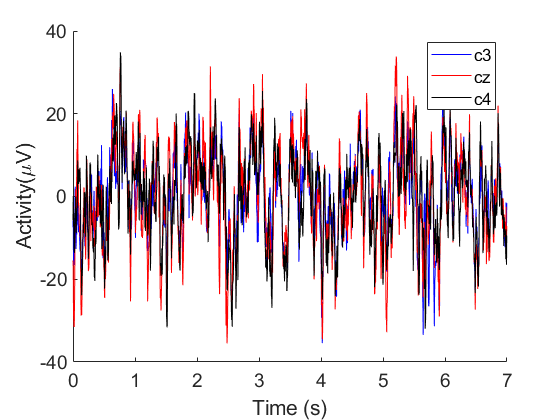

clf;
figure;
hold on;
plot(eeg.time/eeg.fs, eeg.data.rh(1,:,1), 'b')
plot(eeg.time/eeg.fs, eeg.data.rh(1,:,2), 'r')
plot(eeg.time/eeg.fs, eeg.data.rh(1,:,3), 'k')
legend('c3','cz','c4')
hold off;
axis 'auto xy'
xlim([0 7])
set(gca,'FontSize', 14)
set(gca, 'fontname', 'aerial')
xlabel('Time (s)');ylabel('Activity(\muV)')

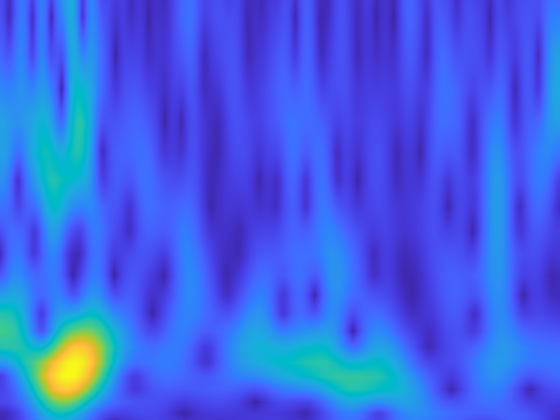

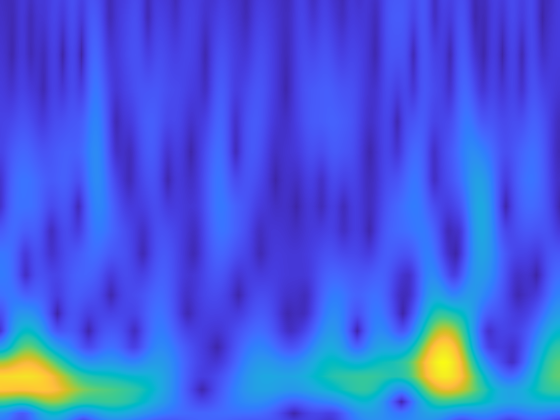

%สร้างชื่อ trial
trial_name = {};
for i=1:length(h.Classlabel)/4
    trial_name = [trial_name, sprintf('trial_%d', i)];
end

usedChannel = {'C3','Cz','C4'};clf;
m = 1;
for j=1:72
    cd('C:\Users\User\Downloads\Compressed\BCICIV_2a_gdf\DATA\LOG');
    cd(trial_name{j});
    for i=1:length(usedChannel)
        sigx = eeg.data.lh(j,:,i);
        [cfs,frq] = cwt(sigx, eeg.fs);
        t = eeg.time/eeg.fs;          
        pcolor(t, frq, abs(cfs));shading 'interp';
        set(gca,'xtick',[],'ytick',[]);
        colormap parula;
        set(gca,'LooseInset',get(gca,'TightInset'));
        ylim([8 30]);
        exportgraphics(gca, sprintf('%s.jpg',usedChannel{i}));
    end
    f1 = imread(sprintf('%s.jpg',usedChannel{1}));
    f2 = imread(sprintf('%s.jpg',usedChannel{2}));
    f3 = imread(sprintf('%s.jpg',usedChannel{3}));
    figx = [f1;f2;f3];
    cd('C:\Users\User\Downloads\Compressed\BCICIV_2a_gdf\DATA\CLASS\LEFT');
    k = (72*m) + j;
    imwrite(figx, sprintf('%d.jpg', k));
end

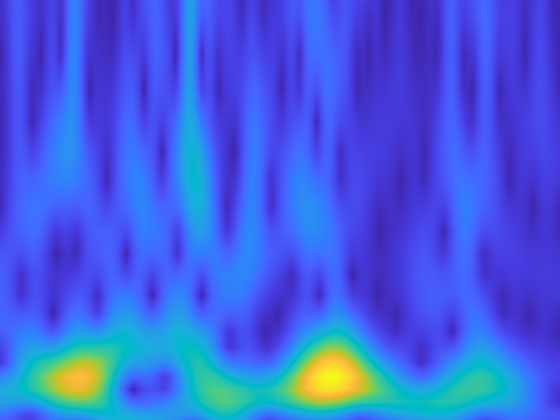

for j=1:72
    cd('C:\Users\User\Downloads\Compressed\BCICIV_2a_gdf\DATA\LOG');
    cd(trial_name{j});
    for i=1:length(usedChannel)
        sigx = eeg.data.rh(j,:,i);
        [cfs,frq] = cwt(sigx, eeg.fs);
        t = eeg.time/eeg.fs;          
        pcolor(t, frq, abs(cfs));shading 'interp';
        set(gca,'xtick',[],'ytick',[]);
        colormap parula;
        set(gca,'LooseInset',get(gca,'TightInset'));
        ylim([8 30]);
        exportgraphics(gca, sprintf('%s.jpg',usedChannel{i}));
    end
    f1 = imread(sprintf('%s.jpg',usedChannel{1}));
    f2 = imread(sprintf('%s.jpg',usedChannel{2}));
    f3 = imread(sprintf('%s.jpg',usedChannel{3}));
    figx = [f1;f2;f3];
    cd('C:\Users\User\Downloads\Compressed\BCICIV_2a_gdf\DATA\CLASS\RIGHT');
    k = (72*m) + j;
    imwrite(figx, sprintf('%d.jpg', k));
end

eeg.full.lh = power(eeg.fil_data.lh,2);
eeg.full.rh = power(eeg.fil_data.rh,2);
eeg.full.fe = power(eeg.fil_data.fe,2);
eeg.full.to = power(eeg.fil_data.to,2);

eeg.full_avg.lh = sum(eeg.full.lh, 1) / 72;
eeg.full_avg.rh = sum(eeg.full.rh, 1) / 72;
eeg.full_avg.fe = sum(eeg.full.fe, 1) / 72;
eeg.full_avg.to = sum(eeg.full.to, 1) / 72;

eeg.rest.lh = eeg.full.lh(:,1:500,:);
eeg.rest.rh = eeg.full.rh(:,1:500,:);
eeg.rest.fe = eeg.full.fe(:,1:500,:);
eeg.rest.to = eeg.full.to(:,1:500,:);

eeg.rest_avg.lh = sum((sum(eeg.rest.lh, 1) / 72), 2)/500;
eeg.rest_avg.rh = sum((sum(eeg.rest.rh, 1) / 72), 2)/500;
eeg.rest_avg.fe = sum((sum(eeg.rest.fe, 1) / 72), 2)/500;
eeg.rest_avg.to = sum((sum(eeg.rest.to, 1) / 72), 2)/500;

erd.lh = movmean(((eeg.full_avg.lh - eeg.rest_avg.lh) ./ (eeg.rest_avg.lh))*100, 50); 
erd.rh = movmean(((eeg.full_avg.rh - eeg.rest_avg.rh) ./ (eeg.rest_avg.rh))*100, 50);
erd.fe = movmean(((eeg.full_avg.fe - eeg.rest_avg.fe) ./ (eeg.rest_avg.fe))*100, 50);
erd.to = movmean(((eeg.full_avg.to - eeg.rest_avg.to) ./ (eeg.rest_avg.to))*100, 50); 

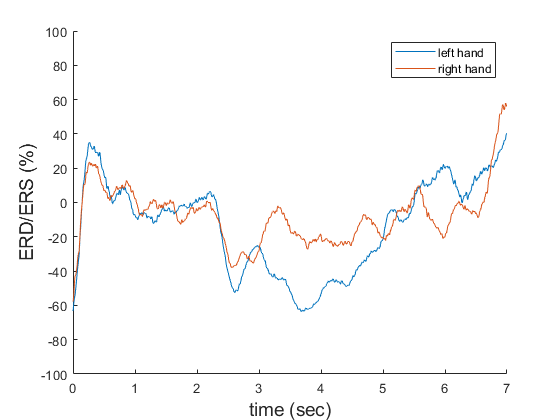

clf;
hold on;
t = 'tongue';
l = 'left hand';
r = 'right hand';
f = 'foot';

plot(eeg.time/eeg.fs, erd.lh(:,:,3));
plot(eeg.time/eeg.fs, erd.rh(:,:,3));
legend(l,r)

cc = 100;
ylim([-cc cc])
% Create ylabel
ylabel('ERD/ERS (%)','FontSize',14,'FontName','Arial');

% Create xlabel
xlabel('time (sec)','FontSize',14,'FontName','Arial');


% Uncomment the following line to preserve the Y-limits of the axes
% Create legend
% set(legend,'FontSize',14,'FontName','Arial');
% print(gcf, name,'-depsc2');
